# 需求分析：高斯拟合法确定光斑中心

- 光斑灰度分布可近似看做高斯分布，可以通过二维高斯函数进行拟合，表达式为：

              
$$f(x,y) = Aexp(-\frac{{(x - x_0)^2}}{{2\sigma _x^2}} -\frac{{(y - y_0)^2}}{{2\sigma _y^2}}) $$


- 其中，$A、x_0、\sigma_x、 y_0、\sigma_y$是待拟合系数。

- 上式两边取对数得到：

              
$$ln(f) = ln(A)-\frac{{(x - x_0)^2}}{{2\sigma _x^2}} -\frac{{(y - y_0)^2}}{{2\sigma _y^2}}=
ln(A)-\frac{{x^2}}{{2\sigma _x^2}} +\frac{{xx_0}}{{\sigma _x^2}}-\frac{{x_0^2}}{{2\sigma _x^2}}-\frac{{y^2}}{{2\sigma _y^2}}+\frac{{yy_0}}{{\sigma _y^2}}-\frac{{y_0^2}}{{2\sigma _y^2}}$$


- 此问题即为一般的二元二次多项拟合问题：

              
$$ln(f)=ax^2+by^2+cx+dy+e  $$


- 其中，$a=-\frac{1}{{2\sigma _x^2}},
b=-\frac{1}{{2\sigma _y^2}},
c=\frac{x_0}{\sigma _x^2},
d=\frac{y_0}{\sigma _y^2},
e=ln(A)-\frac{x_0^2}{{2\sigma _x^2}}-\frac{y_0^2}{{2\sigma _y^2}}$

- 一般思路，通过最小二乘求解，残差平方和最小：

              
$$Q = min\{∑(ax^2+by^2+cx+dy+e  -ln(f))^2\}$$


- 根据最小值条件，分别对$a,b,c,d,e  $求偏导数并令其为零：

              
$$\frac{\partial{Q}}{\partial{a}} = \frac{\partial{Q}}{\partial{b}}=\frac{\partial{Q}}{\partial{c}}=\frac{\partial{Q}}{\partial{d}}=\frac{\partial{Q}}{\partial{e}}=0$$


             
$$\left\{
\begin{array}{l}
2∑(ax^2+by^2+cx+dy+e  -ln(f))x^2=0\\
2∑(ax^2+by^2+cx+dy+e  -ln(f))y^2=0 \\
2∑(ax^2+by^2+cx+dy+e  -ln(f))x=0\\
2∑(ax^2+by^2+cx+dy+e  -ln(f))y=0\\
2∑(ax^2+by^2+cx+dy+e  -ln(f))=0
\end{array} 
\right.$$


- 变形之后得到：

             
$$\left\{
\begin{array}{l}
∑(ax^4+by^2x^2+cx^3+dyx^2+ex^2  )=∑x^2ln(f)\\
∑(ax^2y^2+by^4+cxy^2+dy^3+ey^2 )=∑y^2ln(f)\\
∑(ax^3+by^2x+cx^2+dyx+ex )=∑xln(f)\\
∑(ax^2y+by^3+cxy+dy^2+ey)=∑yln(f)\\
∑(ax^2+by^2+cx+dy+e  =∑ln(f)
\end{array}
\right.$$
             

- 矩阵形式：

            
$$\left[
\begin{array}{l}
\Sigma{x^4} & \Sigma{x^2y^2} & \Sigma{x^3}  & \Sigma{x^2y} & \Sigma{x^2}\\
\Sigma{x^2y^2} & \Sigma{y^4} & \Sigma{xy^2}  & \Sigma{y^3} & \Sigma{y^2}\\
\Sigma{x^3} & \Sigma{xy^2} & \Sigma{x^2}  & \Sigma{xy} & \Sigma{x}\\
\Sigma{x^2y} & \Sigma{y^3} & \Sigma{xy}  & \Sigma{y^2} & \Sigma{y}\\
\Sigma{x^2} & \Sigma{y^2} & \Sigma{x}  & \Sigma{y} & \Sigma{1}             
\end{array}
\right]
\left[
\begin{array}{l}
a\\
b\\
c\\
d\\
e             
\end{array}
\right]
=
\left[
\begin{array}{l}
\Sigma{x^2ln(f)}\\
\Sigma{y^2ln(f)}\\
\Sigma{xln(f)}\\
\Sigma{yln(f)}\\
\Sigma{ln(f)}             
\end{array}
\right]$$


- 求解此方程组即可。

- 此二元二次多项式拟合问题，有更简单的求解方法，参考：[https://zhuanlan.zhihu.com/p/343218641](https://zhuanlan.zhihu.com/p/343218641)

测试图：

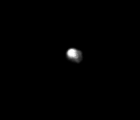

完整代码：

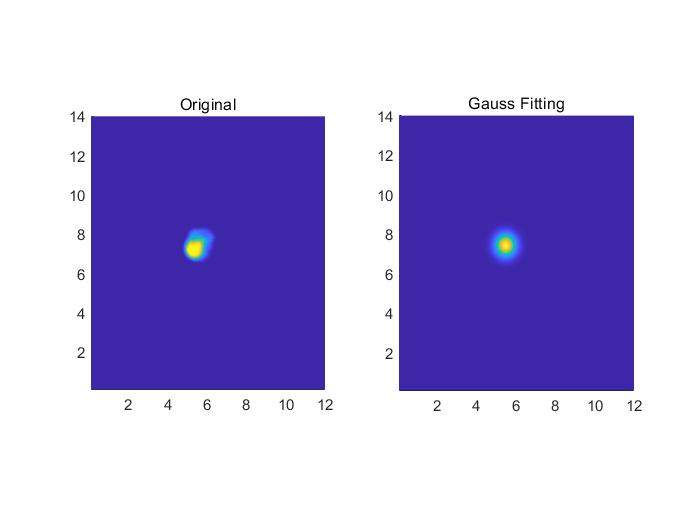

clear; clc;
% x 表示横向，y 表示纵向
imgGrayData = imread('spot.bmp');
% 图像方向和数据方向一致
imgGrayData = imgGrayData';
% 图像大小
[row, col] = size(imgGrayData);     
% 生成网格坐标
[X0, Y0] = meshgrid(1:col, 1:row);   
% 序号太大，拟合效果不好，建议缩小
x0 = X0 / 10;
y0 = Y0 / 10;
% uint8 转换为 double
imgData = double(imgGrayData);                   
% 画原图
subplot(1, 2, 1)
surf(x0, y0, imgData);
% 标题
title('Original');
% smooth
shading interp;     
% 视角
view([-0 90]);
% 等宽
axis equal
% 范围
xlim([0.1, 0.1*col]);
ylim([0.1, 0.1*row]);
% 提取有效数据进行拟合
% 灰度值阈值
thresh = 5;
% 有效数据下标
[rows, cols] = find(imgData >= thresh);
% 有效数据个数
len = length(rows);
% 初始化
xfit = zeros(len, 1);
yfit = zeros(len, 1);
zfit = zeros(len, 1);
for i = 1 : len
    xfit(i) = x0(rows(i), cols(i));
    yfit(i) = y0(rows(i), cols(i));
    zfit(i) = imgData(rows(i), cols(i));
end
% 取对数
zfit = log(zfit);
% 系数矩阵
xfit2 = xfit .* xfit;
yfit2 = yfit .* yfit;
A = [xfit2, yfit2, xfit, yfit, ones(len, 1)];
val = A \ zfit;
% 将拟合结果还原
sigmaX = sqrt(-0.5 / val(1));
sigmaY = sqrt(-0.5 / val(2));
centerX = sigmaX * sigmaX * val(3);
centerY = sigmaY * sigmaY * val(4);
Amp = exp(val(5) + 0.5 * centerX * val(3) + 0.5 * centerY * val(4));
% centerX = round(centerX * 10);
% centerY = round(centerY * 10);
coeFit = [Amp; centerX; sigmaX; centerY; sigmaY];
% 画拟合图
subplot(1, 2, 2)
imgDataFit = coeFit(1) * exp(-(x0 - coeFit(2)).^2 / (2 * coeFit(3) * coeFit(3)) - (y0 - coeFit(4)).^2 / (2 * coeFit(5) * coeFit(5)));
surf(x0, y0, imgDataFit); 
title('Gauss Fitting');
shading interp
view([-0 90]);

axis equal
xlim([0.1, 0.1*col]);
ylim([0.1, 0.1*row]);